% clc;
% clear all;
% close all;

## generate data

run ("Basics.m")

sys =
 
                 1.3 s + 1.333
  --------------------------------------------
  s^4 + 3.967 s^3 + 8.41 s^2 + 10.62 s + 8.756
 
Continuous-time transfer function.



fb = 2.4327

sysd =
 
  0.0004236 z^3 + 0.001167 z^2 - 0.000997 z - 0.0003069
  -----------------------------------------------------
      z^4 - 3.481 z^3 + 4.58 z^2 - 2.697 z + 0.5991
 
Sample time: 0.12914 seconds
Discrete-time transfer function.



c =          0    0.0004    0.0012   -0.0010   -0.0003


d =     1.0000   -3.4807    4.5802   -2.6968    0.5991


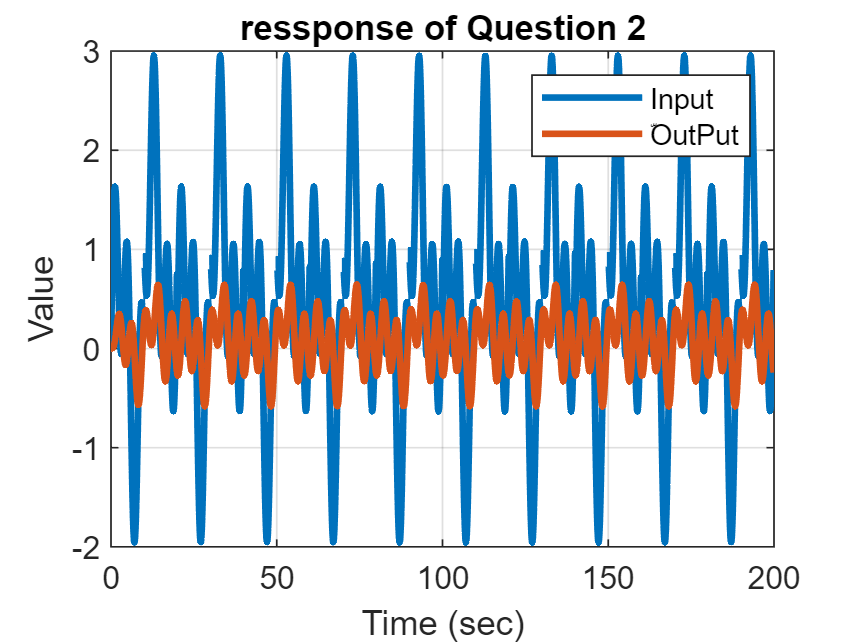

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tfinal=200;
t = 0:T_s:tfinal;
u = gensig('sine' , tfinal/20 , tfinal ,T_s)+gensig('sine' , tfinal/50 , tfinal ,T_s)+gensig('square' , tfinal/10 , tfinal ,T_s);
y = lsim(sysd  ,u ,t);
plot(t,u ,t , y ,'LineWidth',2) ;
xlabel('Time (sec)') ;
ylabel('Value') ;
title('ressponse of Question 2') ;
grid on
legend('Input' , 'ّOutPut') ;

## recursive least esquare estimation

N = numel(y) ;
%choose number of parameters
Parameters_in_den=4

Parameters_in_den = 4

Parameters_in_num=4

Parameters_in_num = 4

Nv=Parameters_in_num+Parameters_in_den

Nv = 8

% Nv = 10 ;
theta(:,1:Nv) = zeros(Nv , Nv) ;
P = 1e8*eye(Nv) ;
phi=[];
Eror=zeros(1,N)

Eror =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i = (max(Parameters_in_num,Parameters_in_den))+1:N
    phi(:,i) = [[y(i-1:-1:i-Parameters_in_den)]' , [u(i-1:-1:i-Parameters_in_num)]']';
    K = P*phi(:,i)*(1+phi(:,i)'*P*phi(:,i))^(-1) ;
    P = (eye(Nv) - K*phi(:,i)')*P ;
    theta(:,i) = theta(:,i-1) + K*(y(i) - phi(:,i)'*theta(:,i-1)); 
    Eror(i)=(Eror(i-1)+(y(i)-phi(:,i)'*theta(:,i))^2);
end

theta1(:,1:Nv) = zeros(Nv , Nv) ;
P1 = 1e8*eye(Nv) ;
phi1=[];
Eror1=zeros(1,N)
for i1 = (max(Parameters_in_num,Parameters_in_den))+1:N
    phi1(:,i1) = [[y(i1-1:-1:i1-Parameters_in_den)]' , [u(i1-1:-1:i1-Parameters_in_num)]']';
    K1 = P*phi1(:,i1)*(1+phi(:,i1)'*P*phi(:,i1))^(-1) ;
    P1 = (eye(Nv) - K*phi1(:,i1)')*P1 ;
    theta1(:,i1) = theta1(:,i1-1) + K1*(y(i) - phi1(:,i1)'*theta1(:,i1-1)); 
    Eror1(i1)=(Eror1(i1-1)+(y(i)-phi1(:,i1)'*theta1(:,i1))^2);
end

ident_dis = tf(theta((Parameters_in_num+1):end,end)' ,[1 -theta(1:Parameters_in_num ,end)'], T_s)

ident_dis =
 
  0.0004257 z^3 + 0.001169 z^2 - 0.0009911 z - 0.0003088
  ------------------------------------------------------
      z^4 - 3.477 z^3 + 4.57 z^2 - 2.688 z + 0.5967
 
Sample time: 0.12914 seconds
Discrete-time transfer function.



ident_analog = d2c(ident_dis)

ident_analog =
 
  1.398e-05 s^3 - 0.0001056 s^2 + 1.305 s + 1.371
  -----------------------------------------------
   s^4 + 3.999 s^3 + 8.526 s^2 + 10.75 s + 8.992
 
Continuous-time transfer function.



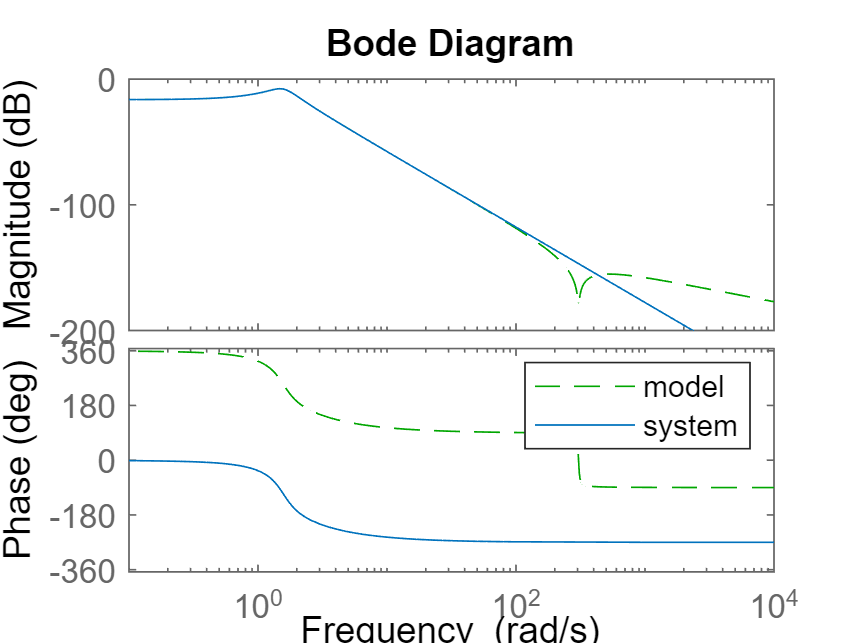

figure
bode(ident_analog ,'g--',sys )
legend('model','system')

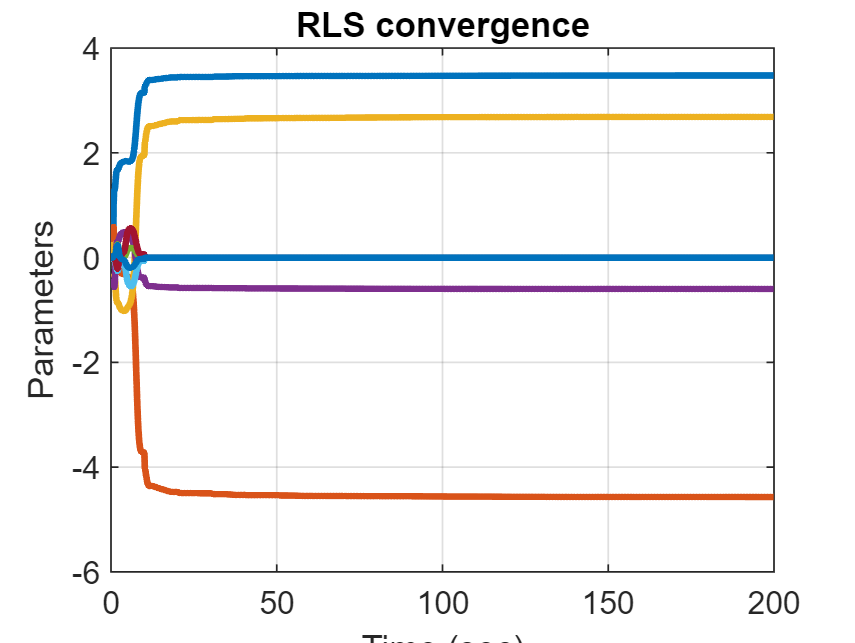

plot(t , theta(:,:) , 'LineWidth' , 2) ;
xlabel('Time (sec)') ;
ylabel('Parameters') ;
title('RLS convergence') ;
grid on

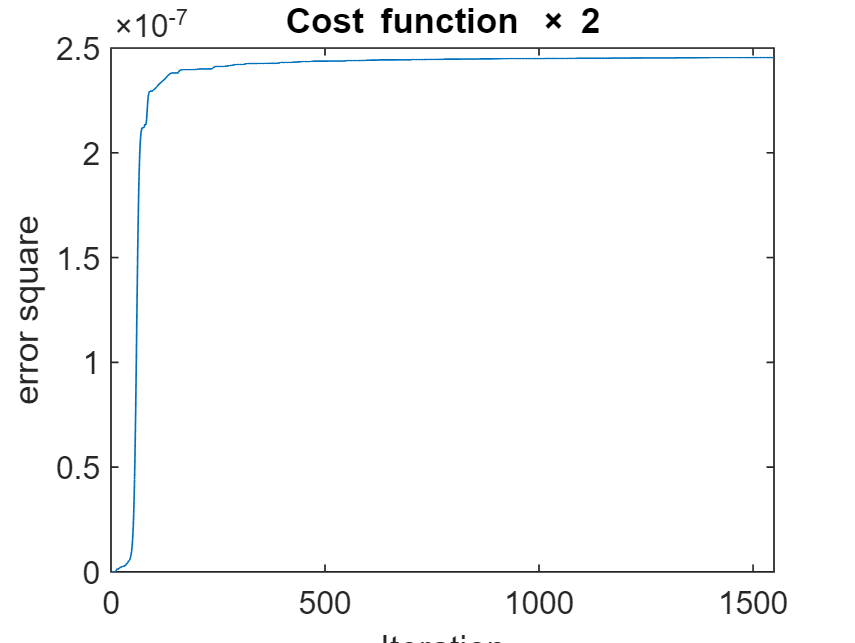

plot(Eror)
xlabel('Iteration') ;
ylabel('error square') ;
title('Cost function \times 2') ;